# Sequence-to-Sequence Classification Using 1-D Convolutions

This example shows how to classify each time step of sequence data using a generic temporal convolutional network (TCN).

PRJ: see also NN models published here: [https://paperswithcode.com/paper/eegnet-a-compact-convolutional-network-for](https://paperswithcode.com/paper/eegnet-a-compact-convolutional-network-for) 

clear all; close all;

## Loading all the data

collectedElectrodes = ["C3", "Cz", "C4"]; % or just simple string "all"
% collectedElectrodes = "all";

DataSetB = EEGDataSet_chunks("../data/hands/BCICIV_calib_ds1b.mat", collectedElectrodes);
DataSetG = EEGDataSet_chunks("../data/hands/BCICIV_calib_ds1g.mat", collectedElectrodes);


Data organization and splitting into training/validation/testing:

tempInputs = [
    DataSetB.EEGToLoad;
    DataSetG.EEGToLoad
    ];

tempOutputs = [
    DataSetB.signalsCueCategoricalOUTPUT;
    DataSetG.signalsCueCategoricalOUTPUT;
    ];

% Filter for strictly equal chunk length:
Inputs = filterHands(tempInputs);
Outputs = filterHands(tempOutputs);


Divide data randomly into **train**, **test** and **validation** datasets

%PRJ - todo: load all data first and then divide it using 'dividerand' to
%define train, test and validation datasets
nChunks=numel(Outputs);
[trainInd,valInd,testInd] = dividerand(nChunks,0.8,0.0,0.2);
 
InTrain = Inputs(1,trainInd);
OutTrain= Outputs(1,trainInd);
% InValid = Inputs(1,valInd);
% OutValid= Outputs(1,valInd);
InTest  = Inputs(1,testInd);
OutTest= Outputs(1,testInd);


Adopt the network to the **Seq-to-Label**:

OutTrain = SeqToLabel(OutTrain);
% OutValid = SeqToLabel(OutValid);
OutTest = SeqToLabel(OutTest);

## Define Deep Learning Model

layers = [
    sequenceInputLayer(3,"Name","input")
    lstmLayer(128,"Name","lstm","OutputMode","last")
    dropoutLayer(0.5,"Name","dropout")
    fullyConnectedLayer(2,"Name","fc")
    softmaxLayer("Name","softmax")
    classificationLayer("Name","classification")];

lgraph = layerGraph(layers);

View the network in a plot.

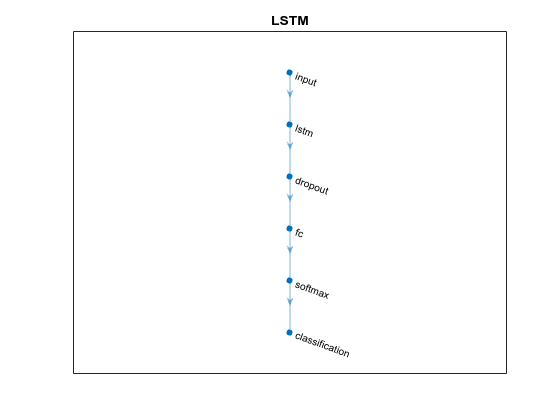

figure
plot(lgraph)
title("LSTM")

## Specify Training Options

Specify a set of options used for training.

- Train for 60 epochs with a mini-batch size of 1.

- Train with a learning rate of 0.001.

- Display the training progress in a plot and suppress the verbose output.

% options = trainingOptions("adam", ...
%     MaxEpochs=200, ...
%     miniBatchSize=20, ...
%     ValidationData={InValid,OutValid}, ...
%     ValidationFrequency=100, ...
%     Plots="training-progress", ...
%     Shuffle="every-epoch", ...
%     Verbose=true);

options = trainingOptions("adam", ...
    MaxEpochs=200, ...
    miniBatchSize=20, ...
    Plots="training-progress", ...
    Shuffle="every-epoch", ...
    Verbose=true);

## Train Model

Training on single GPU.
|========================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Mini-batch  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |     Loss     |      Rate       |
|========================================================================================|
|       1 |           1 |       00:00:02 |       50.00% |       0.9878 |          0.0010 |
|       4 |          50 |       00:00:05 |       75.00% |       0.6062 |          0.0010 |
|       8 |         100 |       00:00:07 |       65.00% |       0.5768 |          0.0010 |
|      11 |         150 |       00:00:08 |       65.00% |       0.5944 |          0.0010 |
|      15 |         200 |       00:00:10 |       60.00% |       0.6532 |          0.0010 |
|      18 |         250 |       00:00:12 |       75.00% |       0.4944 |          0.0010 |
|      22 |         300 |       00:00:14 |       75.00% |       0.

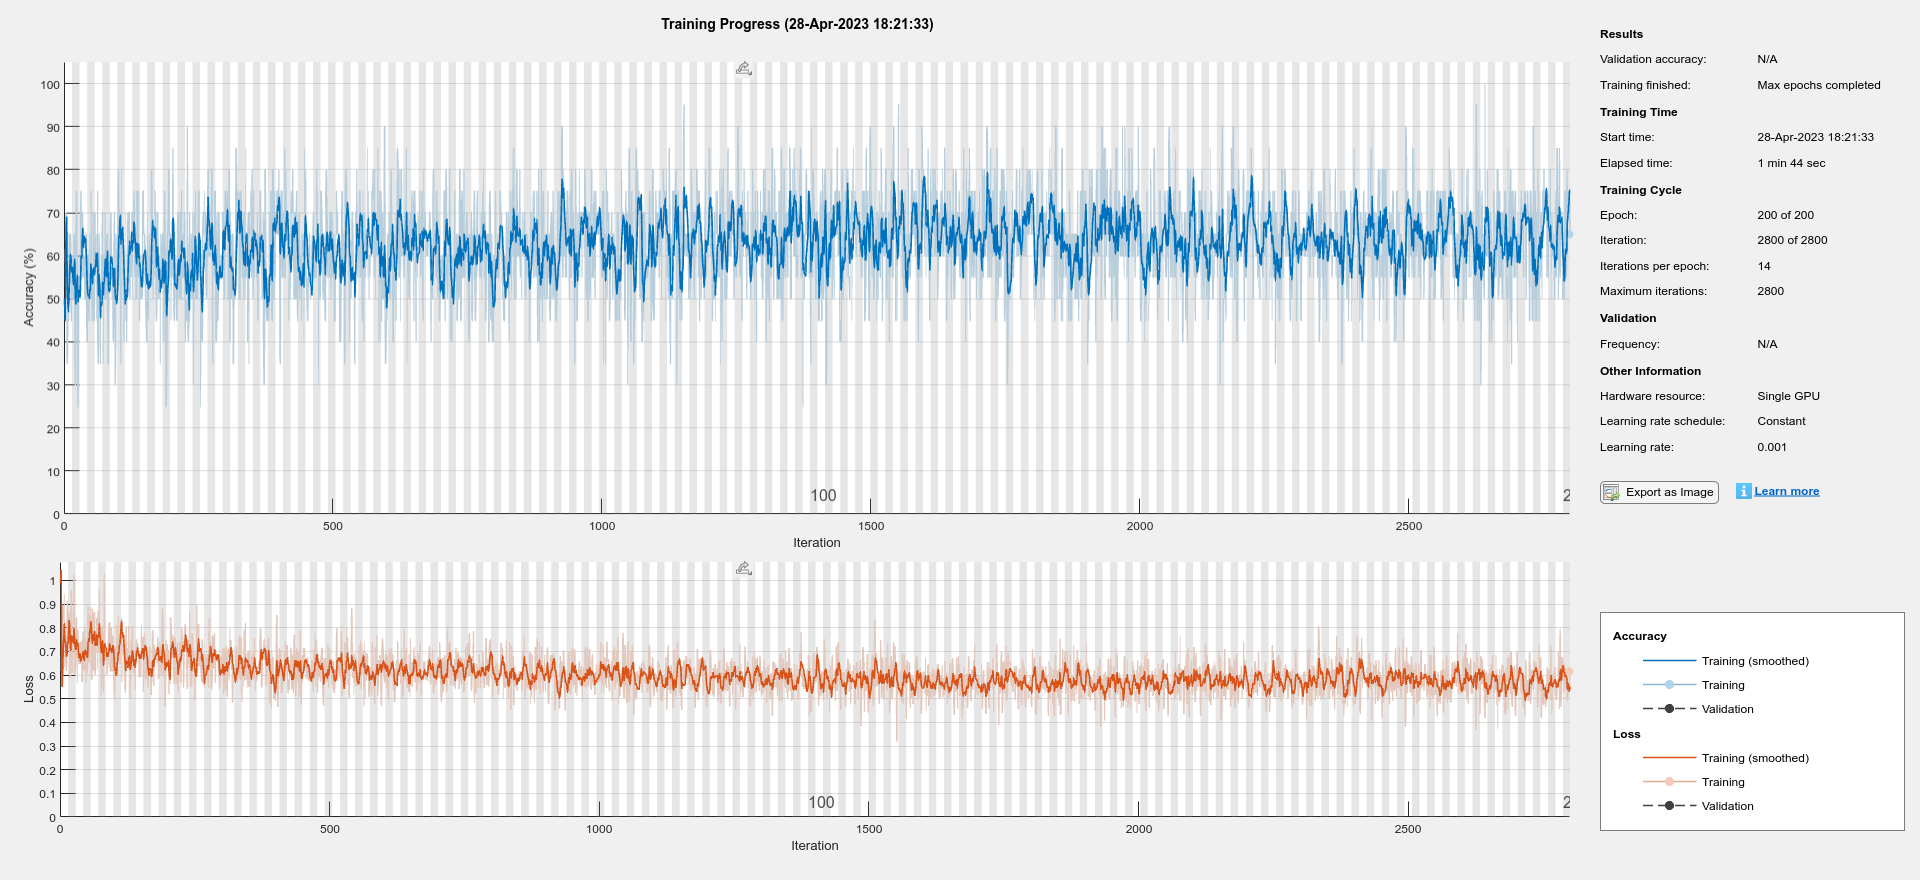

net = trainNetwork(InTrain,OutTrain,lgraph,options);

## Train more

Training on single GPU.
|========================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Mini-batch  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |     Loss     |      Rate       |
|========================================================================================|
|       1 |           1 |       00:00:01 |       45.00% |       0.7423 |          0.0010 |
|       4 |          50 |       00:00:03 |       50.00% |       0.5583 |          0.0010 |
|       8 |         100 |       00:00:05 |       60.00% |       0.6747 |          0.0010 |
|      11 |         150 |       00:00:07 |       40.00% |       0.6722 |          0.0010 |
|      15 |         200 |       00:00:09 |       70.00% |       0.4448 |          0.0010 |
|      18 |         250 |       00:00:10 |       55.00% |       0.5780 |          0.0010 |
|      22 |         300 |       00:00:12 |       75.00% |       0.

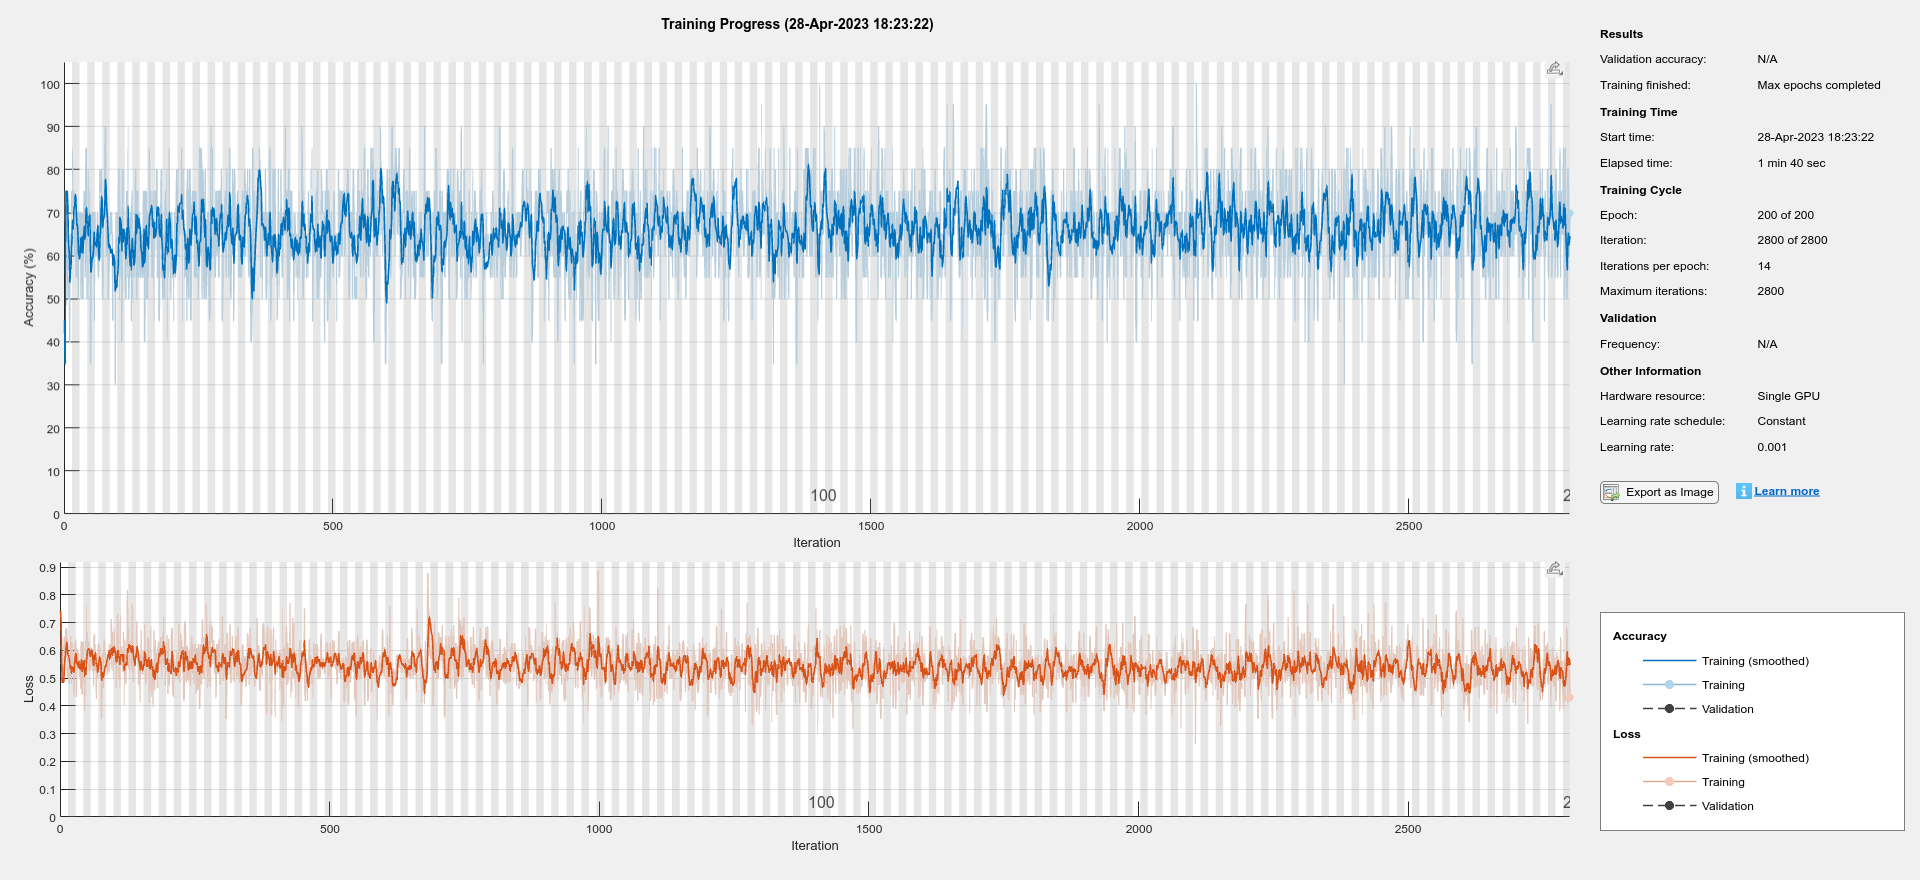

net = trainNetwork(InTrain,OutTrain,layerGraph(net),options);

save('net1.mat',"net");

## Test Model

Test the classification accuracy of the model by comparing the predictions on a held-out test set with the true labels for each time step. 

Use the trained network to make predictions by using the `classify` function.

OutPred = classify(net,InTest);

Visualize the predictions for **each sample** in a confusion matrix.

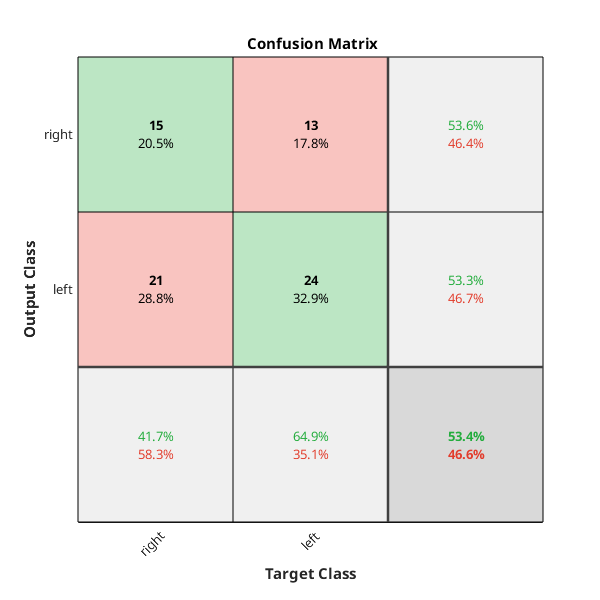

Pred = OutPred;
True = OutTest;
plotconfusion(True(:),Pred(:));

Visualize the predictions for **each sample** in a confusion matrix.

% Pred = vertcat(OutPred{:});
% True = vertcat(OutTest{:});
% PredCount = countcats(Pred');
% Predictions=1*(PredCount(1,:)<PredCount(2,:));
% PredChunk = categorical(Predictions,[0 1],{'EC', 'EO'});
% TrueChunk = True(:,1);
% plotconfusion(TrueChunk(:),PredChunk(:));